# ParaMonte: plain powerful parallel Monte Carlo library

Copyright (C) 2012-present, The Computational Data Science Lab

This file is part of the ParaMonte library.

ParaMonte is free software: you can redistribute it and/or modify it

under the terms of the GNU Lesser General Public License as published

by the Free Software Foundation, version 3 of the License.

ParaMonte is distributed in the hope that it will be useful,

but WITHOUT ANY WARRANTY; without even the implied warranty of

MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE. See the

GNU Lesser General Public License for more details.

You should have received a copy of the GNU Lesser General Public License

along with the ParaMonte library. If not, see,

    [https://github.com/cdslaborg/paramonte/blob/master/LICENSE](https://github.com/cdslaborg/paramonte/blob/master/LICENSE)

#### ACKNOWLEDGMENT

As per the ParaMonte library license agreement terms,

if you use any parts of this library for any purposes,

we ask you to acknowledge the use of the ParaMonte library

in your work (education/research/industry/development/...)

by citing the ParaMonte library as described on this page:

    [https://github.com/cdslaborg/paramonte/blob/master/ACKNOWLEDGMENT.md](https://github.com/cdslaborg/paramonte/blob/master/ACKNOWLEDGMENT.md)

## **Setting up Environment for ParaDRAM sampler**

clc;
clear all;
close all;
fclose('all');
format compact; format long;
file = matlab.desktop.editor.getActiveFilename;
[filepath,~,~] = fileparts(file);
source_dir = filepath + "\..";
addpath(genpath(source_dir));
cd(filepath);

## **Instantiate ParaDRAM_class object**

pmpd = ParaDRAM_class()

pmpd =   ParaDRAM_class with properties:

            spec: [1×1 spec]
           Stats: [1×1 ParaDRAM_Statistics_class]
           Chain: []
    RefinedChain: [1×1 ParaDRAMRefinedChain_class]

## Set ParaDRAM Specifications (Optional)

### ParaMonte variables

pmpd.spec.sampleSize                            = [];   % 10000;
pmpd.spec.randomSeed                            = [];   % 7;
pmpd.spec.description                           = [];   % "Hi there";
pmpd.spec.outputFileName                        = "./out/temp/";
pmpd.spec.outputDelimiter                       = [];
pmpd.spec.chainFileFormat                       = [];   %"compact";
pmpd.spec.variableNameList                      = [];   %["Variable-X", "Variable-Y"];
pmpd.spec.restartFileFormat                     = "ASCII";
pmpd.spec.outputColumnWidth                     = [];   %25;
pmpd.spec.outputRealPrecision                   = [];   %17;
pmpd.spec.silentModeRequested                   = [];   %0;
pmpd.spec.domainLowerLimitVec                   = [];   %[-4,-4];
pmpd.spec.domainUpperLimitVec                   = [];   %[+4,+4];
pmpd.spec.progressReportPeriod                  = [];   %100;
pmpd.spec.targetAcceptanceRate                  = [];   %0.5;
pmpd.spec.maxNumDomainCheckToWarn               = [];   %[];
pmpd.spec.maxNumDomainCheckToStop               = [];   %[];

### ParaMCMC variables

pmpd.spec.chainSize                             = 20000;
pmpd.spec.startPointVec                         = [];   %[0.6,1.2];
pmpd.spec.sampleRefinementCount                 = [];   % 1;
pmpd.spec.sampleRefinementMethod                = [];   % "someRandomName";
pmpd.spec.randomStartPointRequested             = [];   % 1;
pmpd.spec.randomStartPointDomainLowerLimitVec   = [];   % [0.5, 1.0];
pmpd.spec.randomStartPointDomainUpperLimitVec   = [];   % [1.0, 1.5];

### ParaDRAM variables

pmpd.spec.scaleFactor                           = [];   % "1.2 * gelman";
pmpd.spec.proposalModel                         = [];   % "normal";
pmpd.spec.proposalStartCovMat                   = [];   % [0.5, 0.2; 0.1, 0.3];
pmpd.spec.proposalStartCorMat                   = [];   % [0.4, 0.1; 0.2, 0.3];
pmpd.spec.proposalStartStdVec                   = [];   % [1, 1];
pmpd.spec.adaptiveUpdateCount                   = [];   % 2;
pmpd.spec.adaptiveUpdatePeriod                  = [];   % 25;
pmpd.spec.greedyAdaptationCount                 = [];   % 2;
pmpd.spec.burninAdaptationMeasure               = [];   % 0.5;
pmpd.spec.delayedRejectionCount                 = [];   % 2;
pmpd.spec.delayedRejectionScaleFactorVec        = [];   % [3, 4];
pmpd.spec.delayedRejectionCount                 = [];   % 10;
pmpd.spec.delayedRejectionScaleFactorVec        = [];   % [1.1,2,3,1.5,2.1,3,2,1.1,1.2,1.3];

## Set number of dimentions

ndim = 1

ndim =      1

## Set your Objective Function

Please set your objective function at the end of this live script.

## Initiate Sampling

pmpd.runSampler(ndim, @getLogFunc);

************************************************************************************************************************************
************************************************************************************************************************************
****                                                                                                                            ****
****                                                                                                                            ****
****                                                         ParaMonte                                                          ****
****                                                       Version 1.0.0                                                        ****
****                                                        May 23 2018                                                         ****
****                                                                 

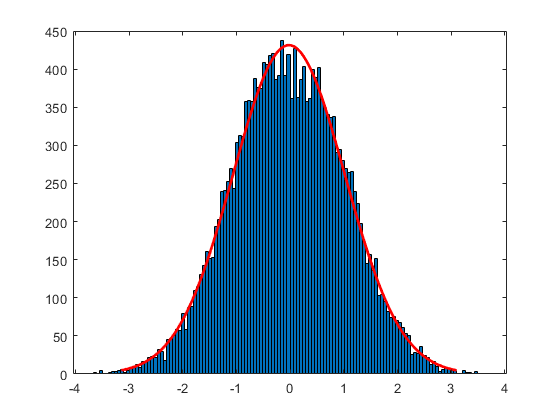

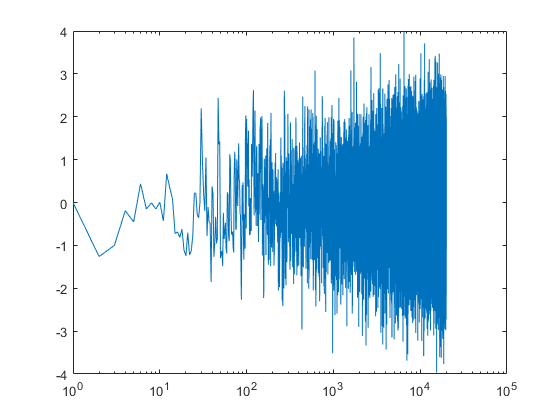

for i = 1 : ndim
    figure;
    histfit(pmpd.Chain.State(i,:));
    figure;
    plot(pmpd.Chain.State(i,:));
    set(gca,'xscale','log')
end

### Run the following code to open report file

%system(pmpd.LogFile.Path.modified);

### Run the following code to open progress file

%system(pmpd.TimeFile.Path.modified);

### Run the following code to open chain file

%system(pmpd.ChainFile.Path.modified);

### Run the following code to open sample file

%system(pmpd.SampleFile.Path.modified);

### Run the following code to open restart file

%system(pmpd.RestartFile.Path.modified);

## Set Objective Function here

This function returns the probability density function of the standard multivariate normal distribution of ndim dimensions.

function logFunc = getLogFunc(point)
    logFunc = -0.5 * sum(point.^2);
end